This live script shows how to, in 1D, 

- initialize all currently defined options for medium parameter class objects

- sample medium parameter objects onto grids.

clear 

domain_x = [0,2]; Nx  = 101;

% Grids and grid spaces
grid_primal = Grid1DUnifPrimal(domain_x,Nx);
gsp_primal   = GridSpace1D(grid_primal);

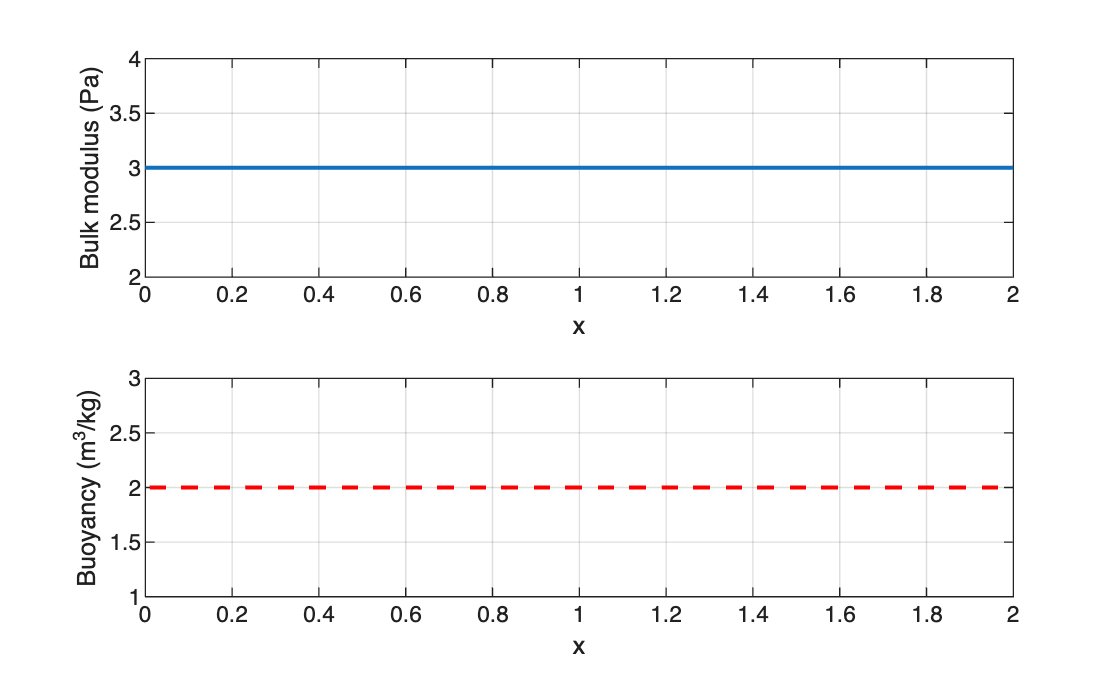

% Define a constant acoustic medium
medium_cnst = AcousticMedium1D.constant(BetaValue=2,KappaValue=3);

% Sample the medium onto the grids
[K_cnst,B_cnst,~,cMax] = sampleMedium1D(gsp_primal,medium_cnst);

figure

subplot(2,1,1)
K_cnst.plot("LineWidth",1.5);
grid on

subplot(2,1,2);
B_cnst.plot("-r","LineWidth",1.5);
grid on

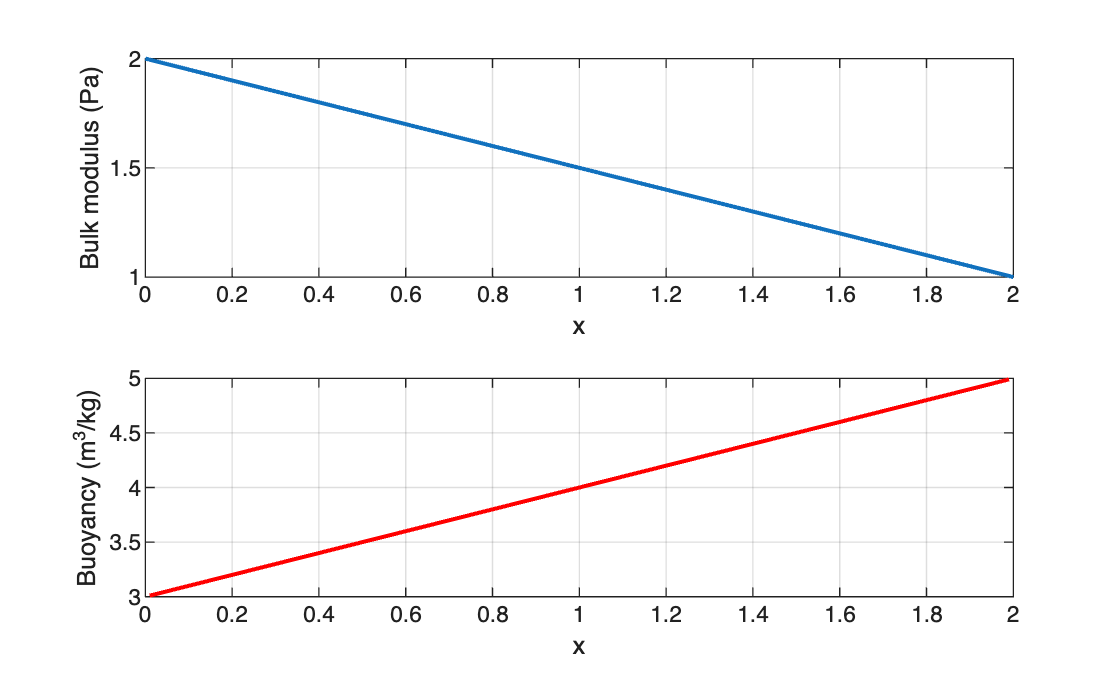

% Define a linear acoustic medium
medium_linear = AcousticMedium1D.linear( ...
    KappaRange = [2,1], ...
    BetaRange  = [3,5], ...
    Domain     = domain_x);

% Sample the medium onto the grids
[K_linear,B_linear] = sampleMedium1D(gsp_primal,medium_linear);

figure

subplot(2,1,1)
K_linear.plot("LineWidth",1.5);
grid on

subplot(2,1,2);
B_linear.plot("-r","LineWidth",1.5);
grid on

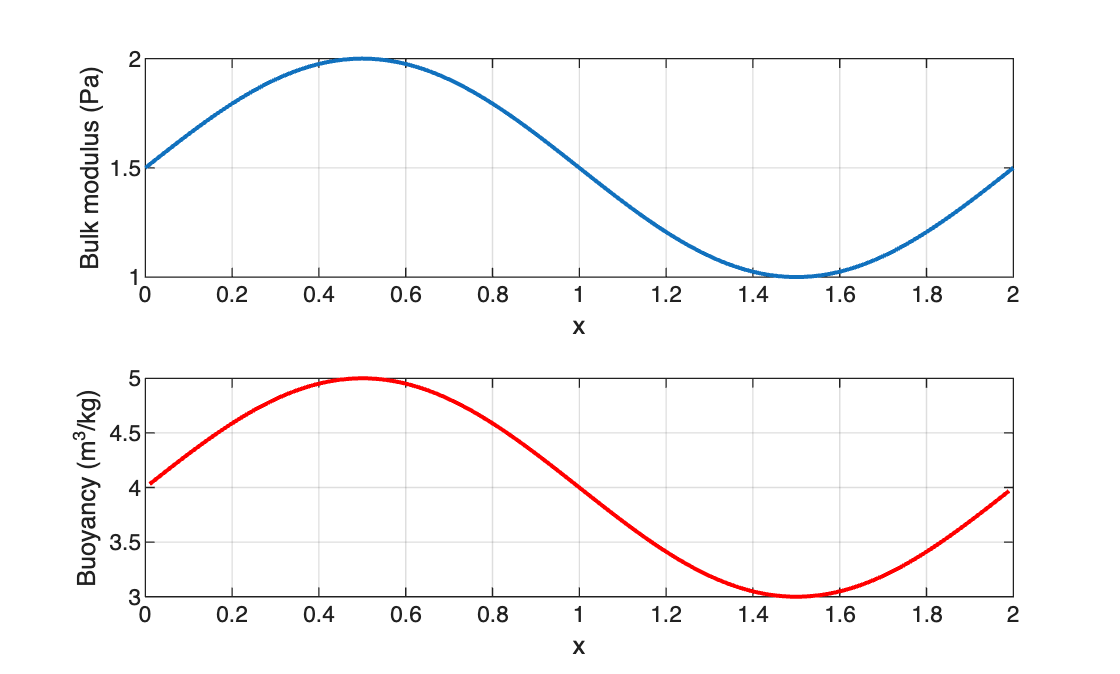

% Define a smooth acoustic medium
medium_smooth = AcousticMedium1D.smooth( ...
    KappaRange = [1,2], ...
    BetaRange  = [3,5], ...
    Domain     = domain_x);

% Sample the medium onto the grids
[K_smooth,B_smooth] = sampleMedium1D(gsp_primal,medium_smooth);

figure

subplot(2,1,1)
K_smooth.plot("LineWidth",1.5);
grid on

subplot(2,1,2);
B_smooth.plot("-r","LineWidth",1.5);
grid on

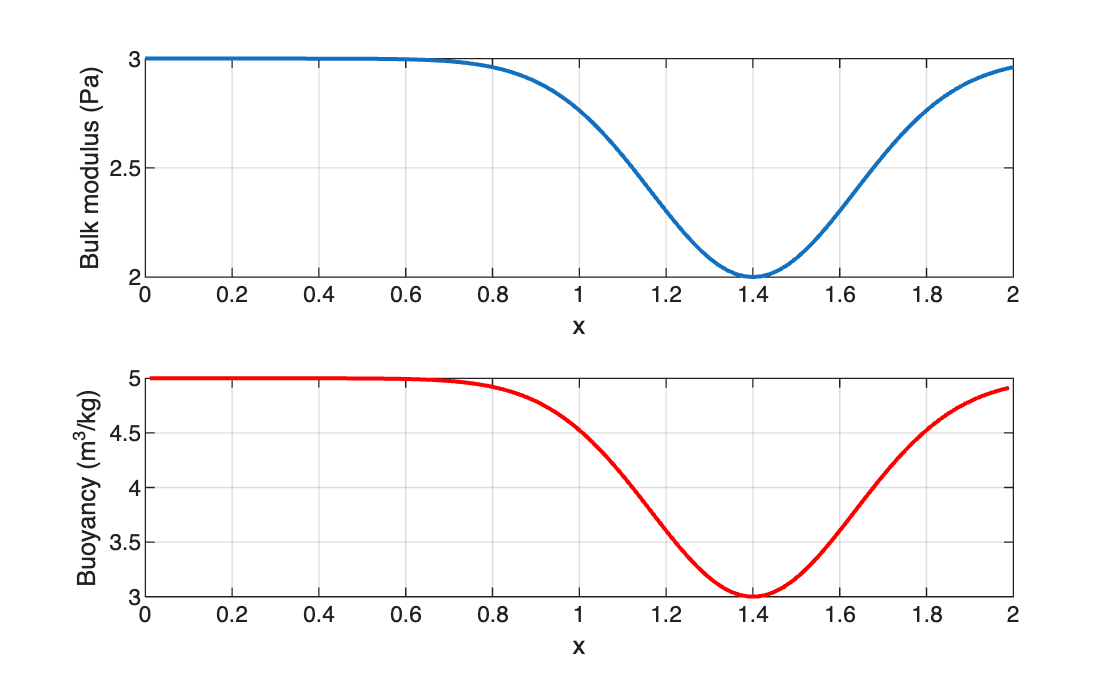

% Define a Gaussian dip acoustic medium
L = diff(domain_x);
xc = domain_x(1) + L*0.7;
medium_gaussDip = AcousticMedium1D.gaussian( ...
    KappaInside  = 2, ...
    KappaOutside = 3, ...
    BetaInside   = 3, ...
    BetaOutside  = 5, ...
    Center     = xc, ...
    Width      = L/6 );

% Sample the medium onto the grids
[K_gaussDip,B_gaussDip] = sampleMedium1D(gsp_primal,medium_gaussDip);

figure

subplot(2,1,1)
K_gaussDip.plot("LineWidth",1.5);
grid on

subplot(2,1,2);
B_gaussDip.plot("-r","LineWidth",1.5);
grid on

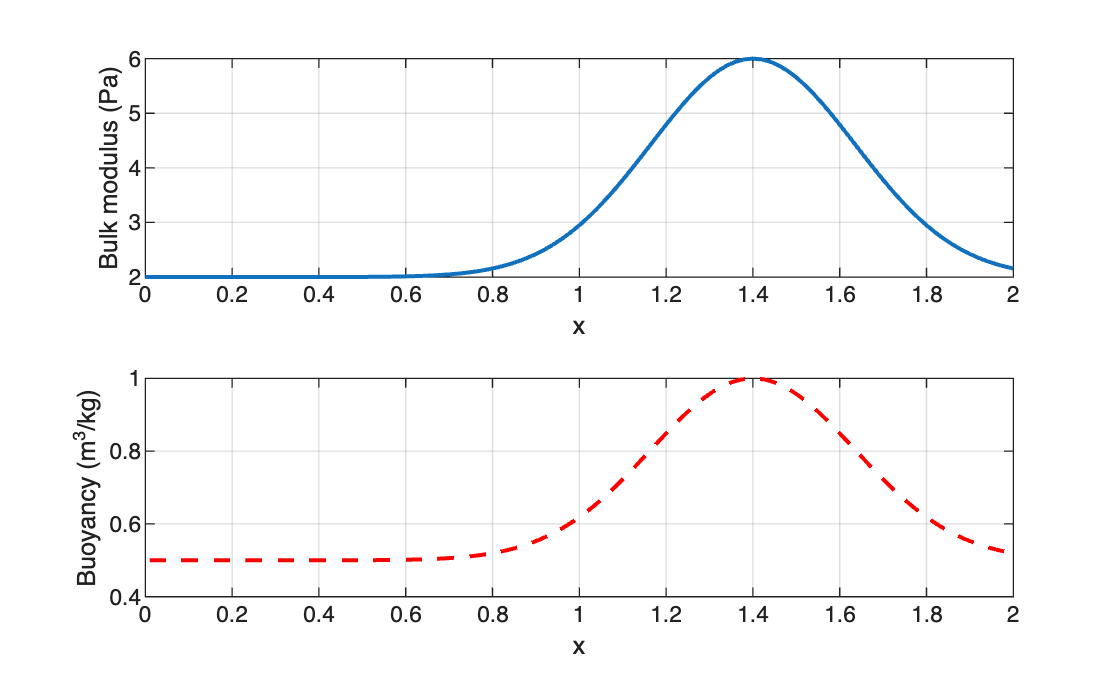

% Define a Gaussian peak acoustic medium
L = diff(domain_x);
xc = domain_x(1) + L*0.7;
medium_gaussPeak = AcousticMedium1D.gaussian( ...
    KappaInside  = 6, ...
    KappaOutside = 2, ...
    BetaInside   = 1, ...
    BetaOutside  = 0.5, ...
    Center     = xc, ...
    Width      = L/6 );

% Sample the medium onto the grids
[K_gaussPeak,B_gaussPeak] = sampleMedium1D(gsp_primal,medium_gaussPeak);

figure

subplot(2,1,1)
K_gaussPeak.plot("LineWidth",1.5);
grid on

subplot(2,1,2);
B_gaussPeak.plot("--r","LineWidth",1.5,"MarkerSize",3);
grid on